close all;
clear;
clc;

**Solve (**$i\ge 1$, $v_0 \;\textrm{and}\;l_0$ are known**):**


$$\left\lbrace \begin{array}{ll}
{a_i \;t}_{i-1}^3 +b_i \;t_{i-1}^2 +c_i \;t_{i-1} +d_i -p_{i-1} =0 & \left(1\right)\\
{a_i \;t}_i^3 +b\;t_i^2 +c\;t_i +d_i -p_i =0 & \left(2\right)\\
3a_{i\;} t_{i-1}^2 +2b_i \;t_{i-1} +c_i -v_{i-1} =0 & \left(3\right)\\
3a_i \;t_i^2 +2b_{i\;} t_i +c_i -v_i =0 & \left(4\right)\\
6a_i \;t_{i-1} +2b_i -l_{i-1} =0 & \left(5\right)\\
6a_i {\;t}_{i\;} +2b_i -l_i =0 & \left(6\right)
\end{array}\right.$$
    

**Subject to:**


$$\left\lbrace \begin{array}{ll}
{0\le v}_i \le v_{\max }  & \textrm{Maximum}\;\textrm{feedrate}\\
{-l_{\max } \le l}_i \le l_{\max }  & \textrm{Maximum}\;\textrm{acceleration}\\
6t_i \left(a_i -a_{i+1} \right)-2\left(b_{i+1} -b_i \right)=0 & C^1 \;\textrm{smoothness}\;\textrm{of}\;\textrm{feedrartes}
\end{array}\right.$$


**6n Unknowns**: $a_i ,b_i ,c_i ,d_i ,v_i ,l_i \;$, **6n equations**, can be solved by **quadratic programming**.

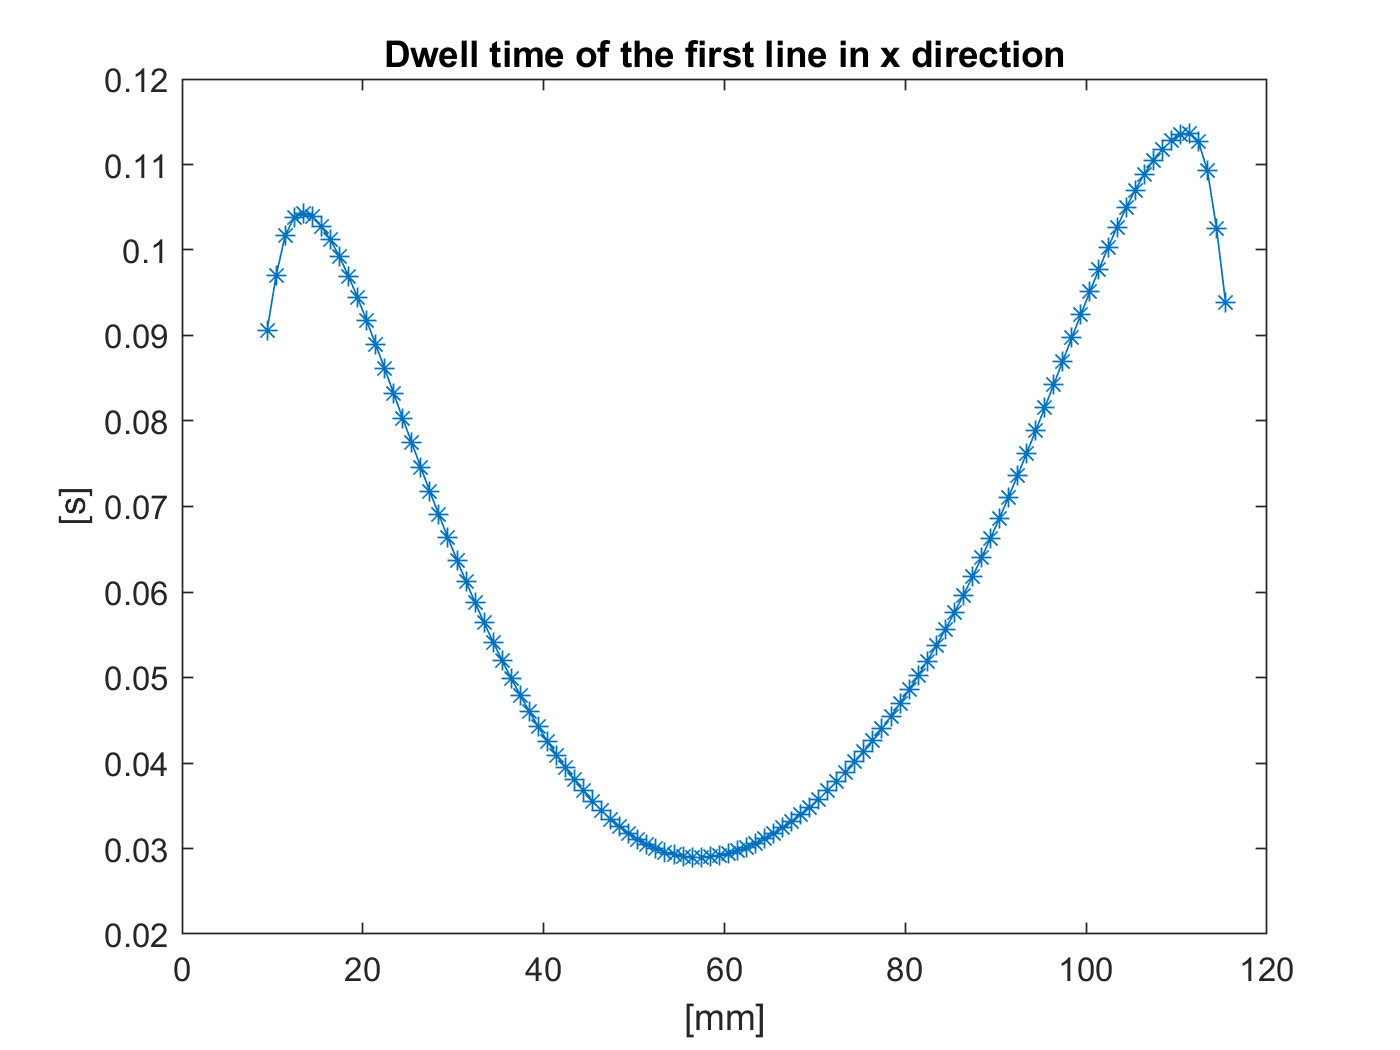

% 1. load an exmample dwell time map (or profile)
data = 'multi_layer_dwell_time_map.mat';
load(data, 'X_P', 't');
T = reshape(t, size(X_P));

% extract one-line profile
t = T(1, :)';
x = X_P(1, :)';

clear 'X_P' 'Y_P' 'T';

figure;
plot(x*1e3, t, '-*');
xlabel('[mm]');
ylabel('[s]');
title('Dwell time of the first line in x direction');

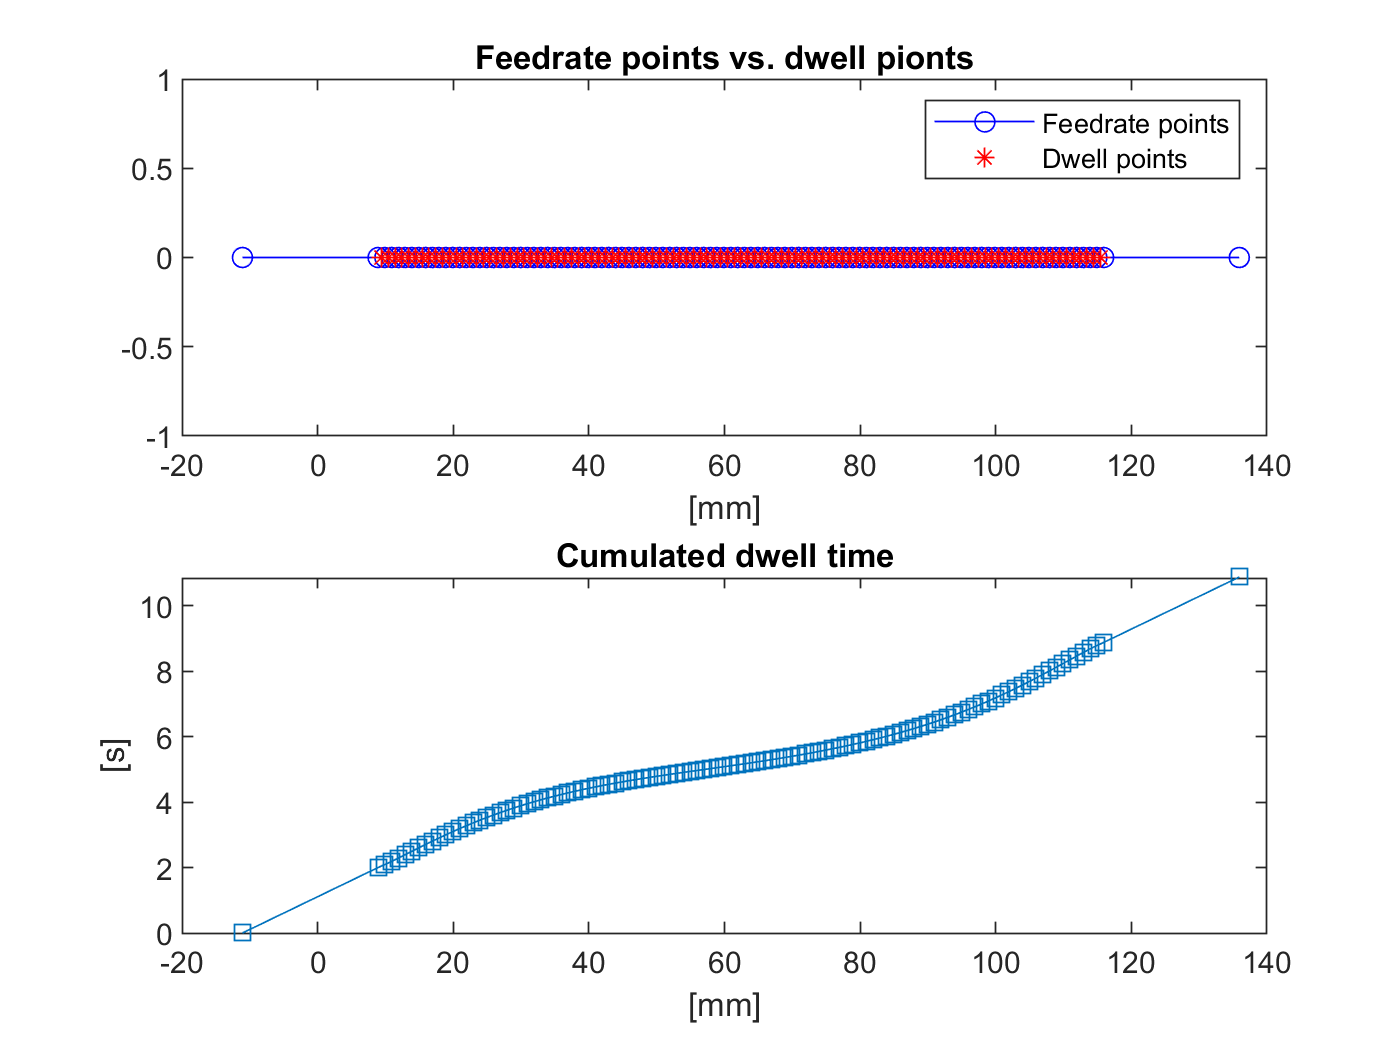

% 2. Generate p and t for pvt
n_dt = length(t);

ex_mv = 20e-3;  % extra move
t_ex = 2;  % extra move time

pvt_p = (diag(ones(1, n_dt + 1)) + diag(ones(1, n_dt), -1)) \ [1.5 * x(1) - 0.5 * x(2); 2*x(:)];
pvt_p = [pvt_p(1) - ex_mv; pvt_p; pvt_p(end) + ex_mv];
pvt_t = cumsum([0; t_ex; t(:); t_ex]);

% pvt_p = (diag(ones(1, n_dt + 1)) + diag(ones(1, n_dt), -1)) \ [1.5 * x(1) - 0.5 * x(2); 2*x(:)];
% pvt_t = cumsum([0; t(:)]);


figure;
subplot(211);
plot(pvt_p*1e3, zeros(size(pvt_p)), 'b-o'); 
hold on;
plot(x*1e3, zeros(size(x)), 'r*'); 
hold off;
title('Feedrate points vs. dwell pionts');
xlabel('[mm]')
legend('Feedrate points', 'Dwell points');

subplot(212);
plot(pvt_p*1e3, pvt_t, 's-');
title('Cumulated dwell time')
xlabel('[mm]');
ylabel('[s]');

**Assemble the matrix (3-points example)**

        
$$\left\lbrack \begin{array}{cccccccccccc}
t_{i-1}^3  & t_{i-1}^2  & t_{i-1}  & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
t_i^3  & t_i^2  & t_i  & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
3t_{i-1}^2  & 2t_{i-1}  & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
3t_i^2  & 2t_i  & 1 & 0 & -1 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
6t_{i-1}  & 2 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
6t_i  & 2 & 0 & 0 & 0 & -1 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & t_i^3  & t_i^{2\;}  & t_{i\;}  & 1 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & t_{i+1}^3  & t_{i+1}^2  & t_{i+1}  & 1 & 0 & 0\\
0 & 0 & 0 & 0 & -1 & 0 & 3t_i^{2\;}  & 2t_{i\;}  & 1 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 3t_{i+1}^2  & 2t_{i+1}  & 1 & 0 & -1 & 0\\
0 & 0 & 0 & 0 & 0 & -1 & 6t_{i\;}  & 2 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 6t_{i+1}  & 2 & 0 & 0 & 0 & -1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a_i \\
b_i \\
c_i \\
d_i \\
v_i \\
l_i \\
a_{i+1} \\
b_{i+1} \\
c_{i+1} \\
d_{i+1} \\
v_{i+1} \\
l_{i+1} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
p_{i-1} \\
p_i \\
v_0 \\
0\\
l_0 \\
0\\
p_{i\;} \\
p_{i+1} \\
0\\
0\\
0\\
0
\end{array}\right\rbrack$$
                           

% 3. Assemble the feedrate optimization for pvt
n_dt = length(pvt_t) - 1;

% boundary & initial conditions
a_max = 2;  % max. acc, m/s^2
v_max = 0.25;  % max. feedrate, m/s
v_min = 0;  % min. feedrate
v_0 = (x(2) - x(1)) / t(1);  % initial feedrate
v_t = (x(end) - x(end - 1)) / t(end);
l_0 = 0;  % initial acc.
l_t = 0;


% % build matrix C and vector d: 6n equations, 6n unknowns
C = zeros(6 * n_dt + 4, 6 * n_dt); 
d = zeros(6 * n_dt + 4, 1);


% equaltity constraints
Aeq = zeros(n_dt - 2, 6 * n_dt);
beq = zeros(n_dt - 2, 1);


for j = 1: n_dt
    i = j + 1;
    id = (j - 1) * 6;
    
    % build C
    C(id + 1, id + 1) = pvt_t(i - 1).^3;
    C(id + 1, id + 2) = pvt_t(i - 1).^2;
    C(id + 1, id + 3) = pvt_t(i - 1);
    C(id + 1, id + 4) = 1;
    
    C(id + 2, id + 1) = pvt_t(i).^3;
    C(id + 2, id + 2) = pvt_t(i).^2;
    C(id + 2, id + 3) = pvt_t(i);
    C(id + 2, id + 4) = 1;
    
    C(id + 3, id + 1) = 3 * pvt_t(i - 1).^2;
    C(id + 3, id + 2) = 2 * pvt_t(i - 1);
    C(id + 3, id + 3) = 1;
    
    C(id + 4, id + 1) = 3 * pvt_t(i).^2;
    C(id + 4, id + 2) = 2 * pvt_t(i);
    C(id + 4, id + 3) = 1;
    C(id + 4, id + 5) = -1;
    
    C(id + 5, id + 1) = 6 * pvt_t(i - 1);
    C(id + 5, id + 2) = 2;
    
    C(id + 6, id + 1) = 6 * pvt_t(i);
    C(id + 6, id + 2) = 2;
    C(id + 6, id + 6) = -1;
    
    if j > 1  
        C(id + 3, id - 1) = -1;
        C(id + 5, id) = -1;        
    end
    
    if j > 1 && j < n_dt
        Aeq(j - 1, id - 5) = 6 * pvt_t(i - 1);
        Aeq(j - 1, id + 1) = -6 * pvt_t(i - 1);
        Aeq(j - 1, id - 4) = 2;
        Aeq(j - 1, id + 2) = 2;
    end
       
    d(id + 1) = pvt_p(i - 1);
    d(id + 2) = pvt_p(i);
        
end
% build d
d(end - 3: end) = [v_0; l_0; v_t; l_t];
C(end - 3, 5) = 1;
C(end - 2, 6) = 1;
C(end - 1, end - 1) = 1;
C(end, end) = 1;

% bounding constraints
lb = NaN(6 * n_dt, 1);
lb(5: 6: end) = v_min;
lb(6: 6: end) = -a_max;
lb(isnan(lb)) = -Inf;

ub = NaN(6 * n_dt, 1);
ub(5: 6: end) = v_max;
ub(6: 6: end) = a_max;
ub(isnan(ub)) = Inf;


% solve
% res = C \ d;
res = lsqlin(C, d, [], [], Aeq, beq, lb, ub);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



pvt_v = [v_0; res(5: 6: end)];
pvt_l = [l_0; res(6: 6: end)];


%%
v_0 = pvt_v(2);  % initial feedrate
v_t = pvt_v(end - 1);

% build d
d(end - 3: end) = [v_0; l_0; v_t; l_t];
C(end - 3, 5) = 1;
C(end - 2, 6) = 1;
C(end - 1, end - 1) = 1;
C(end, end) = 1;

% solve
res = lsqlin(C, d, [], [], Aeq, beq, lb, ub);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


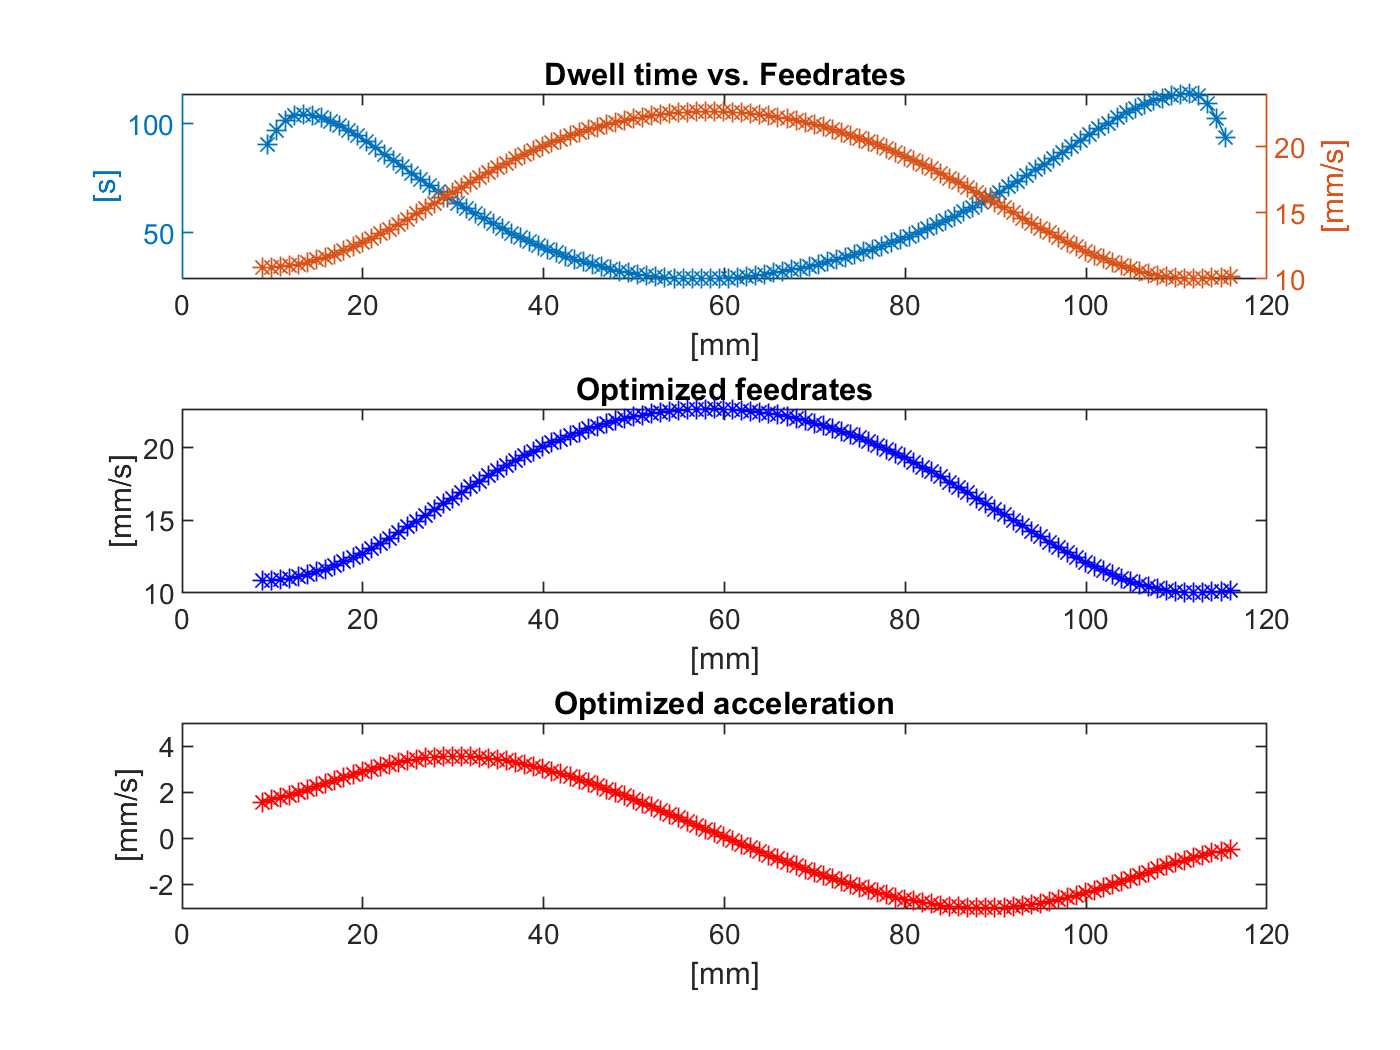


pvt_v = [v_0; res(5: 6: end)];
pvt_l = [l_0; res(6: 6: end)];

pvt_v = pvt_v(2: end - 1);
pvt_l = pvt_l(2: end - 1);
pvt_p = pvt_p(2: end - 1);

figure;
subplot(311);
yyaxis left;
plot(x*1e3, t*1e3, '-*');
ylabel('[s]');

yyaxis right;
plot(pvt_p*1e3, pvt_v*1e3, '-*');
title('Dwell time vs. Feedrates');
xlabel('[mm]');
ylabel('[mm/s]');

subplot(312);
plot(pvt_p*1e3, pvt_v*1e3, 'b-*');
title('Optimized feedrates');
xlabel('[mm]');
ylabel('[mm/s]');

subplot(313);
plot(pvt_p*1e3, pvt_l*1e3, 'r-*');
title('Optimized acceleration');
xlabel('[mm]');
ylabel('[mm/s]');